# Characterize Motor Inertia and Friction using Simulink Design Optimization

## Execute Coastdown Experiment

#### Open Test Bench and Setup Coast Down Experiment

mdl = 'FieldOrientedController_RCP';
open_system(mdl);
switchConfig('RCP');
switchMotorKit('SG_Inverter_RCP_Kit');

Select Signal Editor Experiement 

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario','Coastdown_Test'); % Select Experiment

#### Build Model for Speedgoat Real-Time Target

rtwbuild(mdl); % Build Model

#### Run Experiment

tg = slrt;
load(tg,mdl);
tg.StopTime = 5;
tg.start; pause(5);

#### Plot Results

expRun = Simulink.sdi.Run.getLatest;
expRun.Name = ['CoastdownExp - ' char(expRun.DateCreated)];
sigExp = getSignalsByName(expRun,'rotorVelocity');
Simulink.sdi.setSubPlotLayout(1,1);
sigExp.Checked = true; % Mark Signal for Plotting
Simulink.sdi.view % Open Simulation Data Inspector UI

## Or Load Data from Past Experiment

prj = currentProject;
%load([prj.RootFolder{1},'\Data\CoastDownExperimentData.mat']);
load([prj.RootFolder{1},'\Data\CoastDownExperimentData_SG.mat']);
expRun = Simulink.sdi.Run.create;
expRun.Name = 'CoastdownExp_Recorded';
expRun.add('vars',data);
rotorVelocity = getSignalsByName(expRun,'rotorVelocity');
rotorVelocity.Checked = true;
Simulink.sdi.view

## Compare Experiment Result with Desktop Simulation 

mdl = 'FieldOrientedController_MIL';
open_system(mdl);
switchConfig('MIL');
%switchMotorKit('SG_Inverter_RCP_Kit');

#### Select Signal Editor Experiement 

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario','Coastdown_Test'); % Select Experiment

#### Restore Initial Inertia and Friction Coefficient Values

%Initial Inertia and Friction Coefficient Values
dd=Simulink.data.dictionary.open('SGKitPlantData.sldd');
setValue(getEntry(getSection(dd,'Design Data'),'discInertia'),5e-5);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmInertia'),8.35e-05);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmCoulombFrictionTorque'),1e-3);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmViscousFrictionCoefficient'),9e-5);
% Simulate Model
sim(mdl,'StopTime','5');

#### View and Compare Data in Simulation Data Inspector

desktopRun = Simulink.sdi.Run.getLatest;
desktopRun.Name = ['Coastdown Sim - ' char(desktopRun.DateCreated)];
sigSim = getSignalsByName(desktopRun,'rotorVelocity');
sigSim.Checked = true; % Mark Signal for Plotting
Simulink.sdi.view; % Open Simulation Data Inspector 

## Estimate Disc Inertia and Viscous Friction Coefficient using "spetool"

spetool('CoastDown_SPE_Session');

### Coastdown response before parameter estimation 

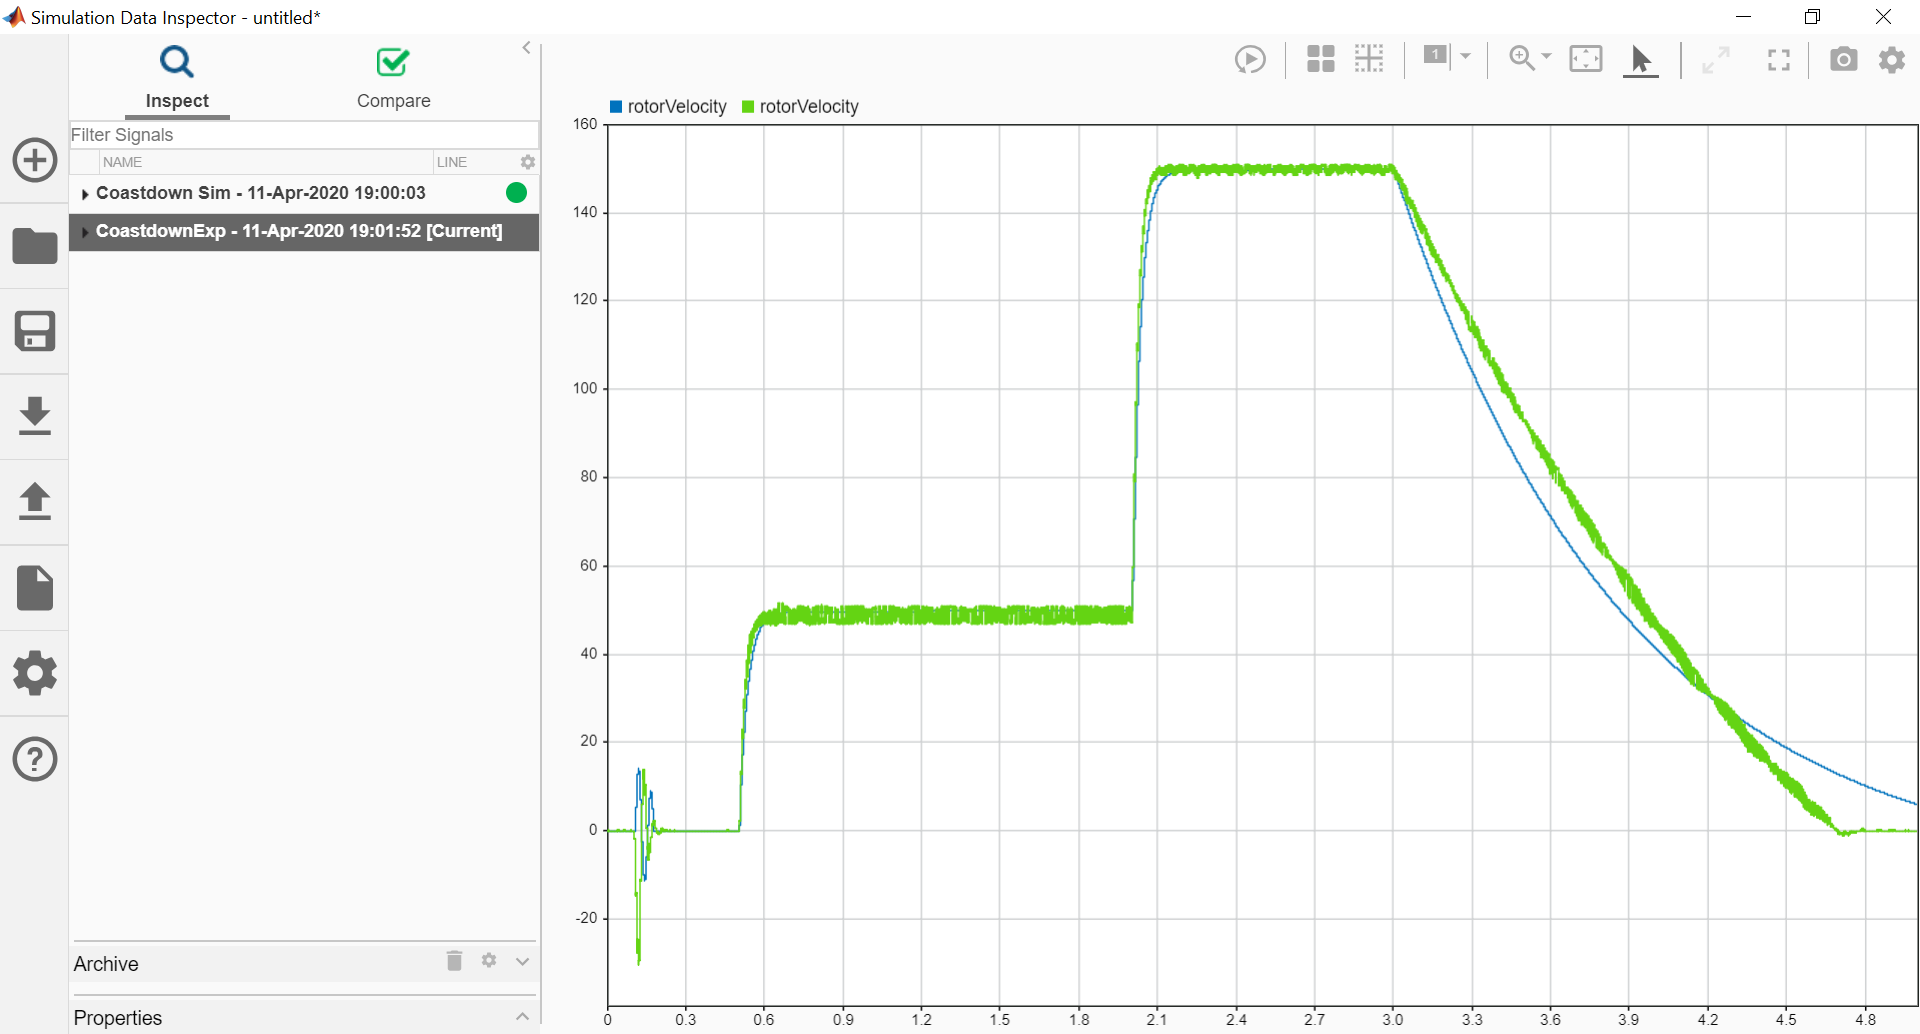

### Coastdown response after parameter estimation 

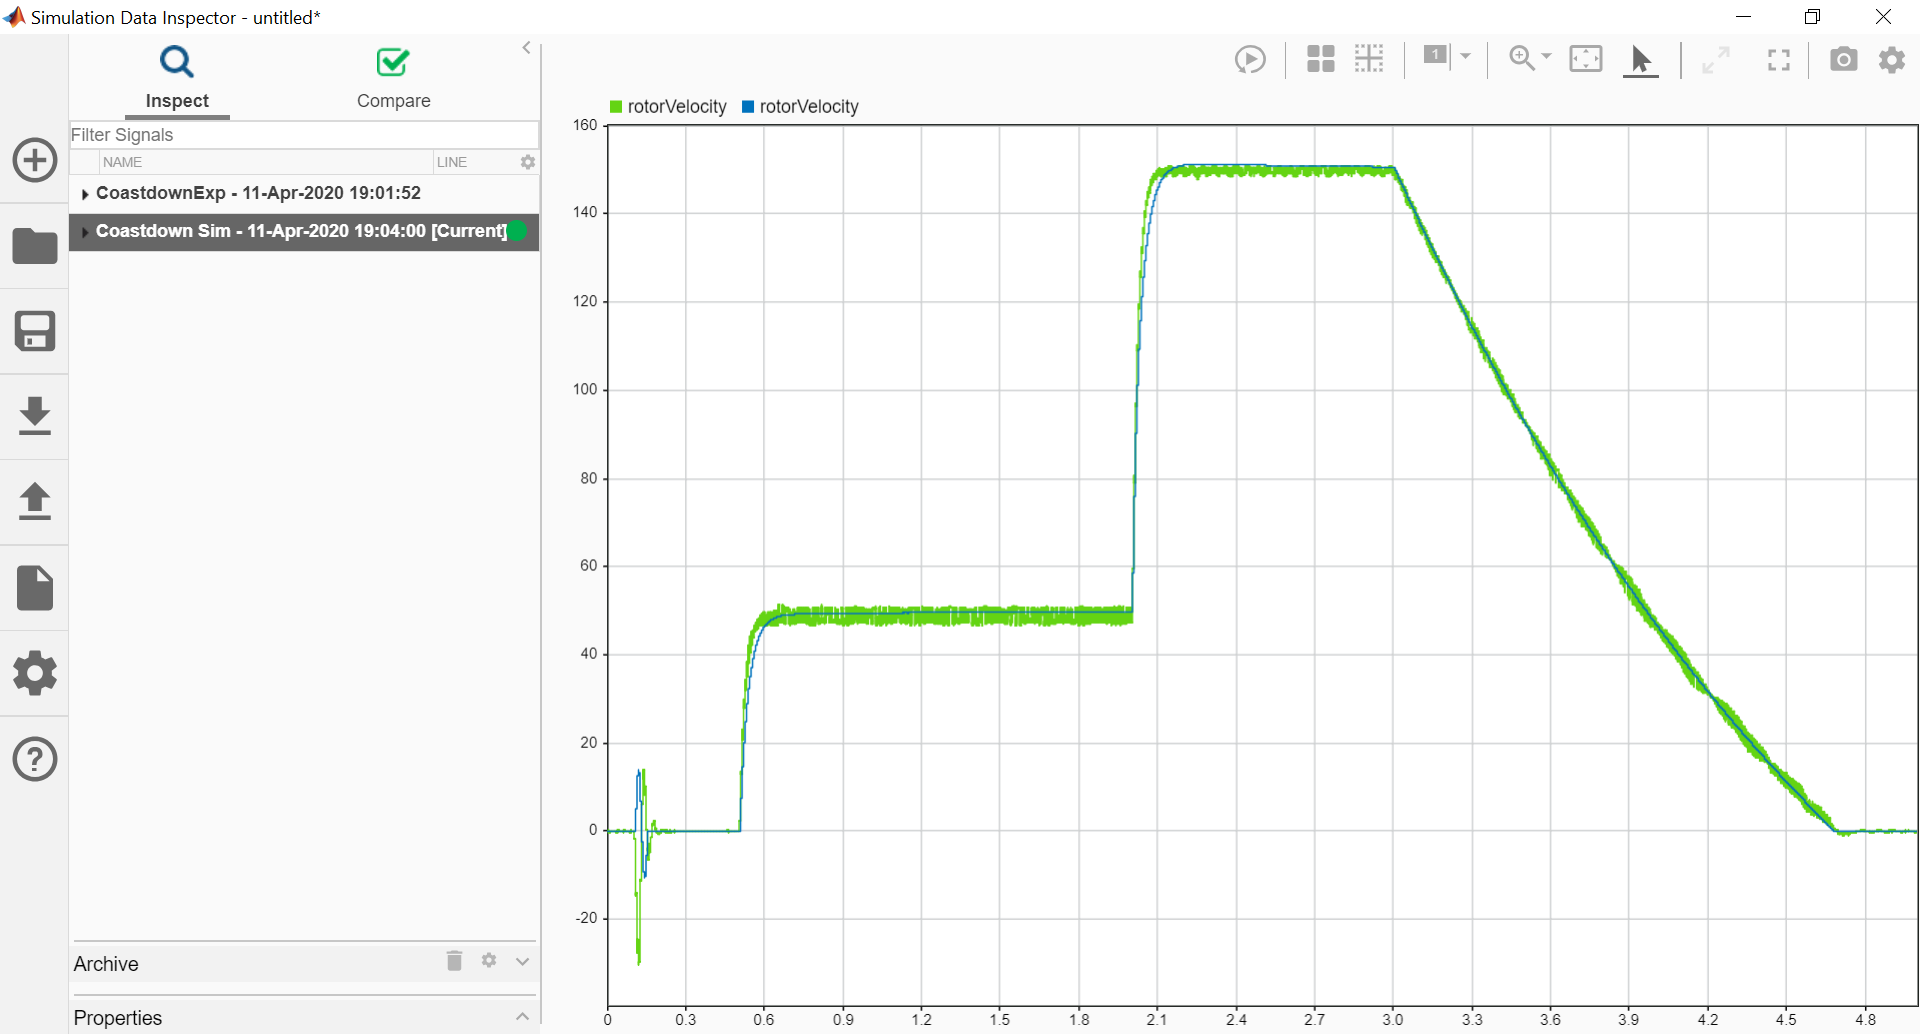

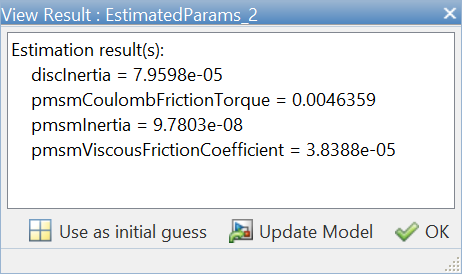

## **Restore Data Dictionary**

dd.discardChanges;
clear mdl sigSim tg expRun desktopRun sigExp sigSim dd